# Simulate Sphere Image

## User inputs

%system
p.f = 1;
p.p = 1e-6;
%target
p.d = 7;
p.r = 2000e3;
p.rho = 1;
p.sV = [1,1,1];
%sim
p.osf = 100; 

## Analysis

%simulate sun going around diagonally
theta = pi/4

theta = 0.7854

phi = pi/4

phi = 0.7854

h=figure

h =   Figure (3) with properties:

      Number: 3
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [1000 818 560 420]
       Units: 'pixels'

  Show all properties


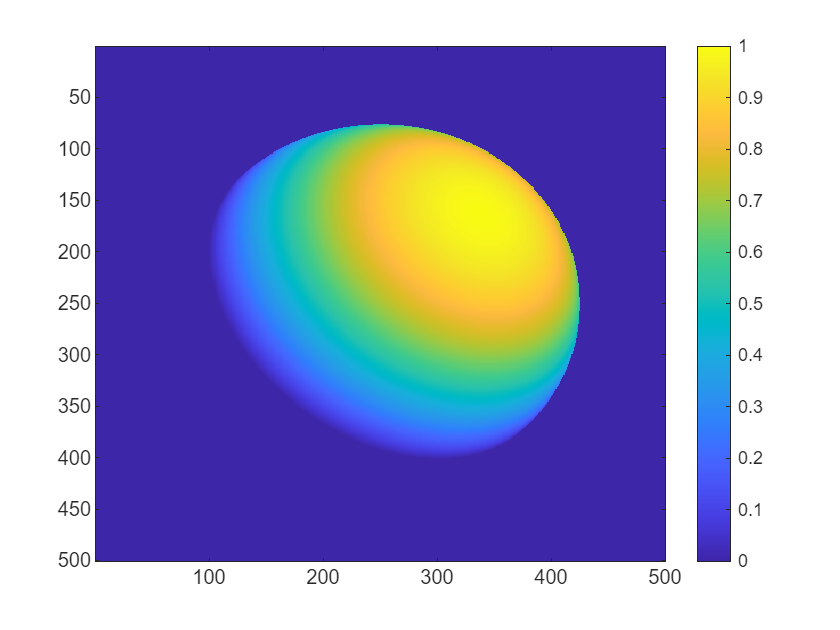

for i = 1:length(theta)
    p.sV = [sin(theta(i)).*cos(phi),sin(phi).*sin(theta(i)),cos(theta(i))];
    [im,N] = sphereIm(p,0,'Odd');
    figure(h)
    imagesc(N,[0,1]); colorbar
    drawnow
    pause
end

## Gen Sphere Function

function [im,N] = sphereIm(p,plotTF,EvenOrOddOrIgnore) 
    % Sample SPhere
    IFOV = atan(p.p/p.f);
    tgtAng = atan(p.d/p.r);
    tgtPix=tgtAng/IFOV; %How many pixels the target subtends
    if tgtPix<1 %if it is a subpixel target just use the phase equation
        ang = acos(dot([0,0,1],p.sV));
        F = 2/3/pi^2*((pi-ang)*cos(ang)+sin(ang));
        if strcmp(EvenOrOddOrIgnore,'Even')
            im = [1,1;1,1]*.25*F;
        else
            im = F;
        end
    else    
        phs = 0; %This term is used to help us ensure even or odd images
        if mod(ceil(tgtPix),2)==1 && strcmp(EvenOrOddOrIgnore,'Even')
            phs = 1;
        elseif mod(ceil(tgtPix),2)==0 && strcmp(EvenOrOddOrIgnore,'Odd')
            phs = 1;
        end
        sams = ceil(tgtAng/IFOV+phs)*p.osf;  %How many pixels we'll use to sample
        scl=sams/(tgtPix*p.osf); %We need to scale up our radial sampling to account for the sphere not filling the entire thing.
         
         
        % Here we are going to create 2D theta and phi LUTs to get samples of a
        % sphere
         
         
        % Create 2D direction vectors for a square to calculate Phi
        [X,Y] = meshgrid(linspace(-scl,scl,sams),linspace(-scl,scl,sams));
        R = sqrt(X.^2+Y.^2);
        phi = acos(dot(cat(3,X./R,Y./R),repmat(cat(3,1,0),[size(X),1]),3));
        phi(end/2+1:end,:)=2*pi-phi(end/2+1:end,:);
         
         
        %use the radial image to calculate theta
        theta = pi/2-abs(acos(R));
         
         
        % For each subpixel sample, map it to a unit vector on the sphere.
        V = cat(3,sin(theta).*cos(phi),sin(phi).*sin(theta),cos(theta));
        msk = R; msk(R<1)=1; msk(R>1)=nan;
        V=V.*repmat(msk,[1,1,3]);
         
        %Calc dot of normal with the sun 
        N=dot(V,repmat(reshape(p.sV,[1,1,3]),[size(R),1]),3)/norm(p.sV);
        N(N<0)=0;
        N(isnan(N))=0;
         
        %Downsample
        
        for i = 1:ceil(tgtPix+phs)
            for j = 1:ceil(tgtPix+phs)
                im(i,j)=sum(N([1:p.osf]+p.osf*(i-1),[1:p.osf]+p.osf*(j-1)),"all")/p.osf^2;
            end
        end   
    end
     
    if plotTF
        figure
        subplot(1,3,1)
        imagesc(V(:,:,1)); title('x'); colorbar
        subplot(1,3,2)
        imagesc(V(:,:,2)); title('y'); colorbar
        subplot(1,3,3)
        imagesc(V(:,:,3)); title('z'); colorbar
        
        figure
        R2 = sqrt(sum(V.^2,3));
        imagesc(R2); title('R (to make sure its all 1)')
        
        figure
        subplot(1,2,1)
        imagesc(N); colorbar
        subplot(1,2,2)
        imagesc(im); colorbar
    end 
end









